# **LAB 4**

## Problem 1

- Import the file

h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:);

    2.  Graph the particle count data vs time to see if there are any patterns

time = mydata(:,1);

sunPosition = mydata(:,2);

earthPosition = mydata(:,3);

particleCounts = mydata(:,4);

    Let's see how the particle number per unit time varies

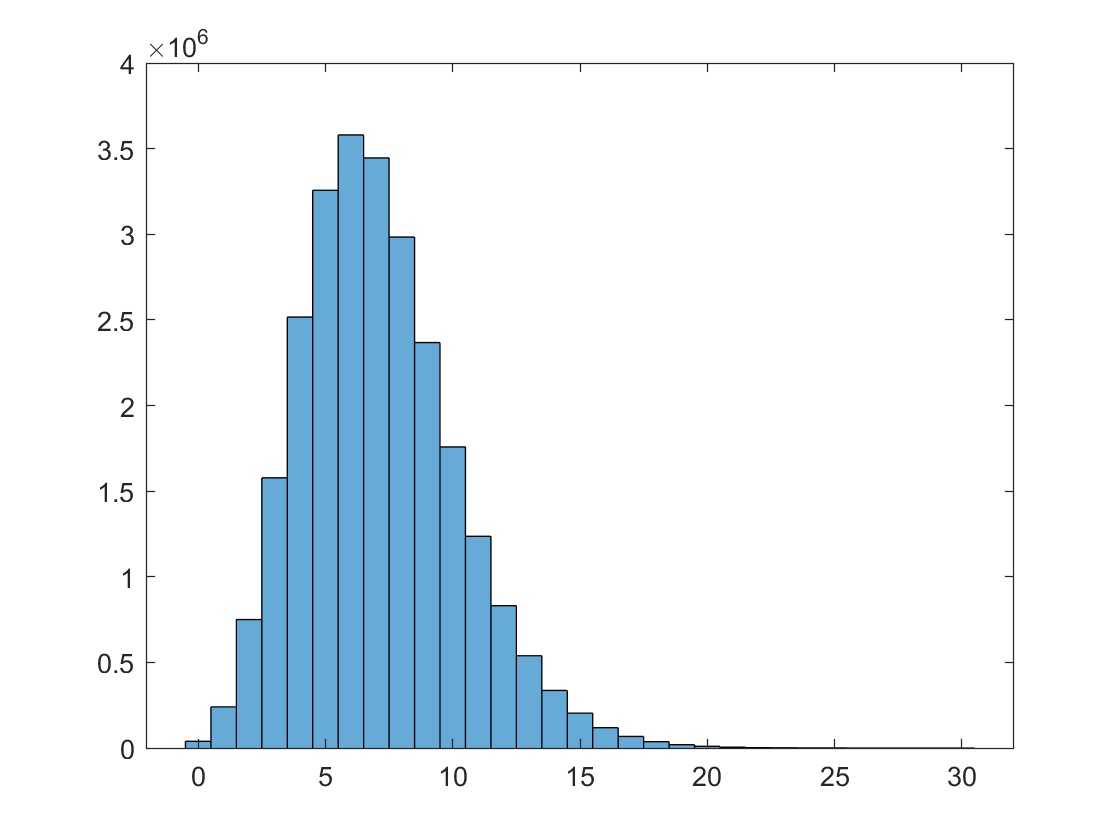

histogram(mydata(:,4))

It seems to be a Poisson distribution, which makes sense because there are multiple independent variables that affect the particle count at each unit time

3. Next, plot particle count vs time 2d histogram to see the trends

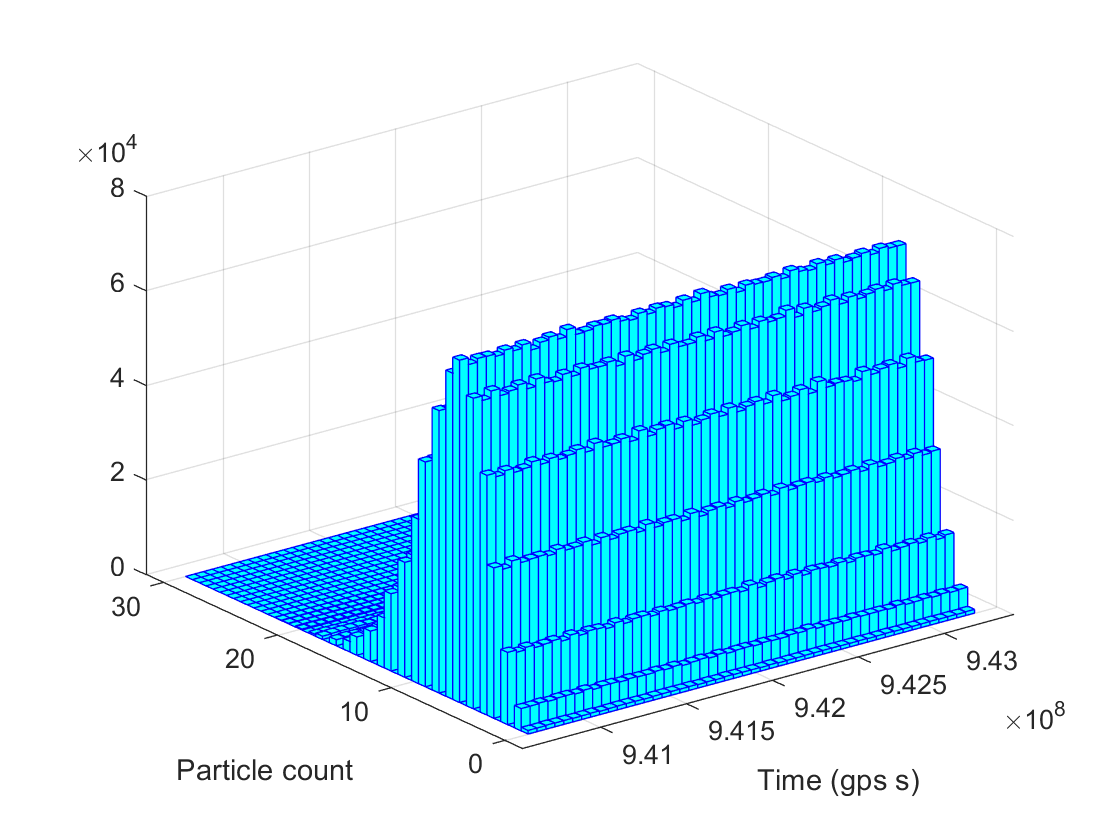

hist3([mydata(:,1) mydata(:,4)], [50 50], "EdgeColor","blue","FaceColor","cyan")
xlabel('Time (gps s)')
ylabel('Particle count')

It doesnt seem like there are trends where the average particle count shifts with time passing visible to naked eye from this compressed into 100*100 histogram.

Now plot sunPosition vs Partice Counts to see the relationship between them

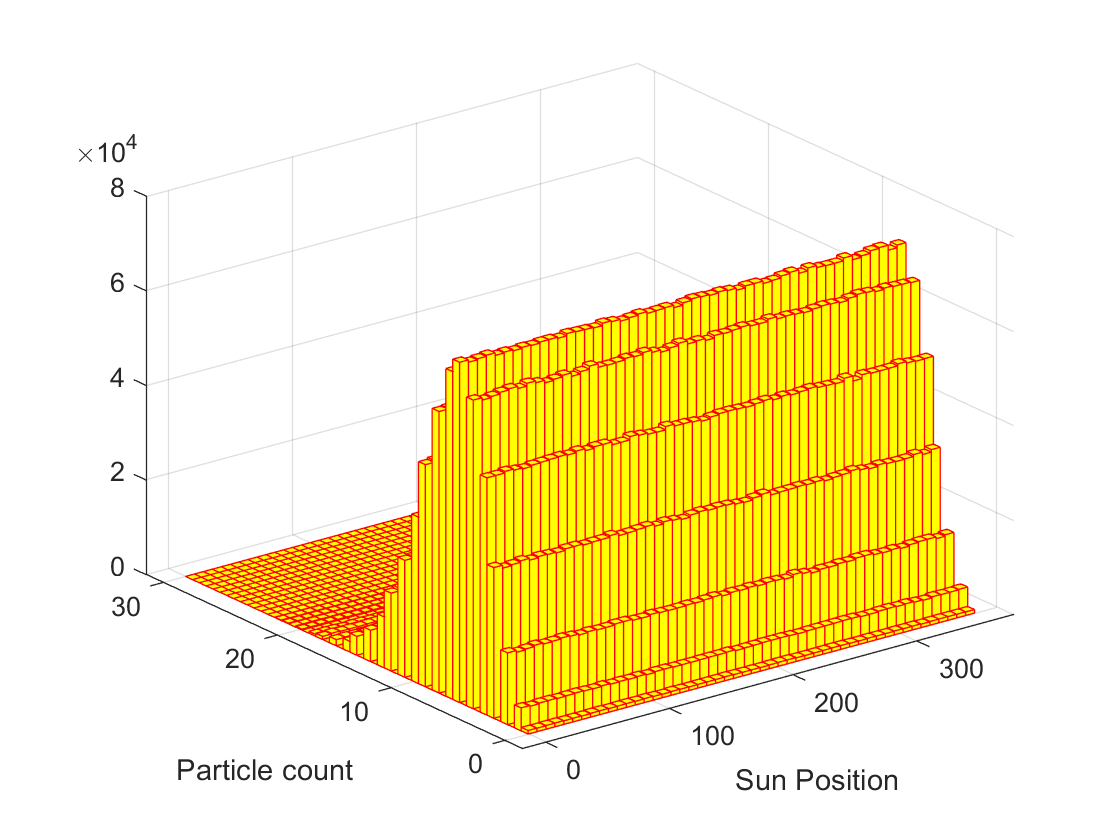

hist3([mydata(:,2) mydata(:,4)], [50 50], "EdgeColor","red","FaceColor","yellow")
xlabel('Sun Position')
ylabel('Particle count')

It doesn't seem like sun positioin affects the number of particles either. The mean stays in the same place with different sun positions therefore it is safe to assume that the sun position does not affect the number of gamma rays detected.

earthPosition vs Particle Count

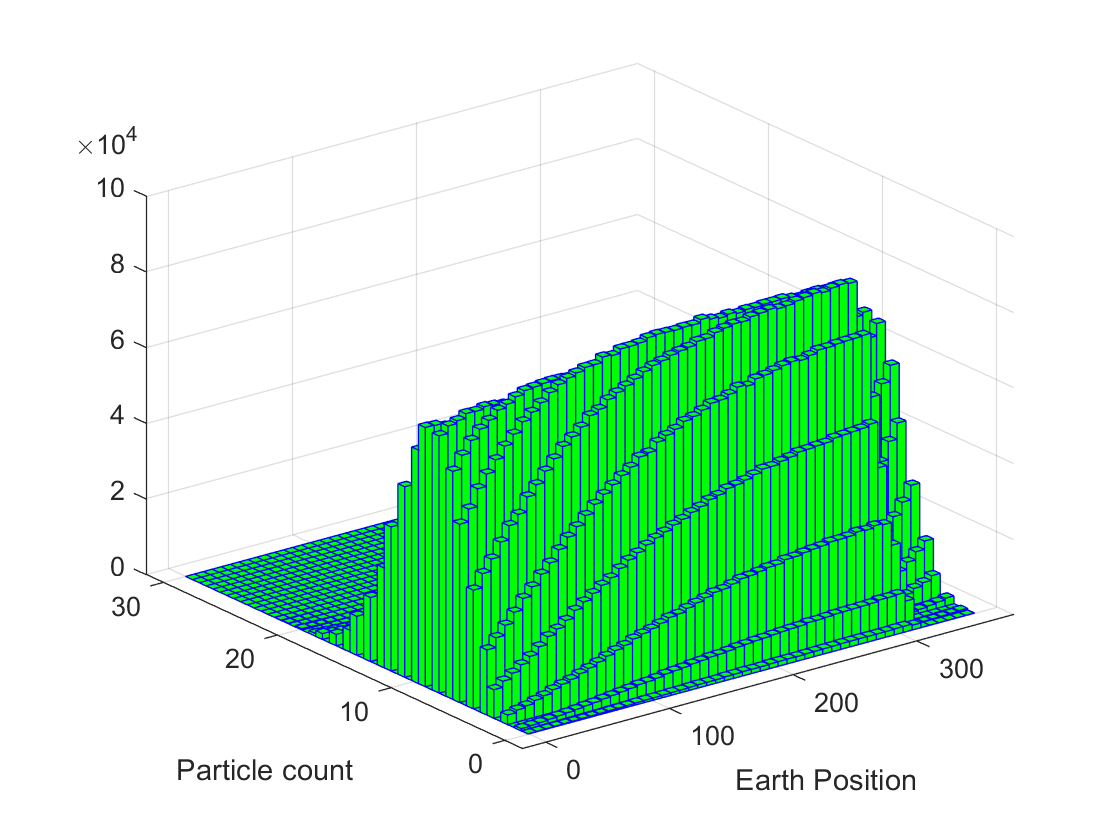

hist3([mydata(:,3) mydata(:,4)], [50 50], "EdgeColor","blue","FaceColor","green")
xlabel('Earth Position')
ylabel('Particle count')

It seems like when Earth Position is in between values 300 and 350, the particle count is increased from an average of 10 to an average of 15 looking at the graph. Also, there is less bins with low particle count when earth positon number is lower.

Let's plot the time vs earth position to see how earths position changes and how many times

plot(mydata(:,1),mydata(:,3), 'Linewidth', 4)
xlabel('time')
ylabel('earth position')

From this graph one can tell that earth's position cycles many times and not much more.

To derive the background from the given data, I can 

- calculate the deviation of the mean associated with earth's position from the mean across the data

- calculate the standard deviation for each mean associated with earth's specific position and see if it varies and if it should be included in the calculation

- create data that corresponds to the difference from the mean which is the predicted background data

The value of earth's position vary by 1/3*0.001 degrees so if there is a total of 360 degrees, then the number of positions is

numberOfEarthPositions = 360/(1/3*0.001);
earthPosition = zeros(numberOfEarthPositions,1);
earthPosition(1) = 0;
for i = 2:numberOfEarthPositions
    earthPosition(i) = earthPosition(i-1)+(1/3*0.001);
end

For each earthPosition, create a distribution of values similar to the one in histogram but not 

lengthDist = length(mydata(:,3)/numberOfEarthPositions);
particles = zeros(numberOfEarthPositions,1)

particles =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 1:numberOfEarthPositions
end

Background is going to be described as a matrix where for each earth position there is going to be the difference of mean of that position from the average mean, and the sigma difference from average sigma.

avMean = mean(mydata(:,4));
avDeviation = std(mydata(:,4));
background = zeros(lengthDist,3)

background =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


for i = 1:lengthDist 
end

If I completed implementing that code I believe my background distribution would've been good

## Problem 2

a) download images

h5disp("images.h5")
mydata2 = h5read("images.h5",'/image1')
mydata3 = h5read("images.h5",'/imagestack')